# DC Motor Position Control Multi GA - Simulink

The script solves a nonlinear optimization problem for Tuning PID gain values of DC Motor Position Control

## Include Parameters or Data

Set the initial point `x0` and scale `a` for the optimization.

tic % starting stop watch timer

% clearing workspace and command window screen
clc;
clear;

x0 = [0;0;0];       % lower bound values
x1 = [25 0.5 0.5]   % upper bound valuew

x1 =    25.0000    0.5000    0.5000



a = 100;

nVar = 3;       % number of variables

**Place the **`x0`** value and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task


Multi-objective optimization:
3 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1            20                 1                 1
    2            40          0.113022          0.979025
    3            60          0.118722          0.587868
    4            80        0.00458062          0.724531
    5           100                 0                 0
    6           120         0.0481508          0.321034
    7           140         0.0161646         0.0246353
    8           160        0.00993642        0.00924348
    9           180          0.050783          0.353683
   10           200         0.0311933         0.0380045
   11           220        0.00790012        0.00947733
   12           240         0.0434101         0.0

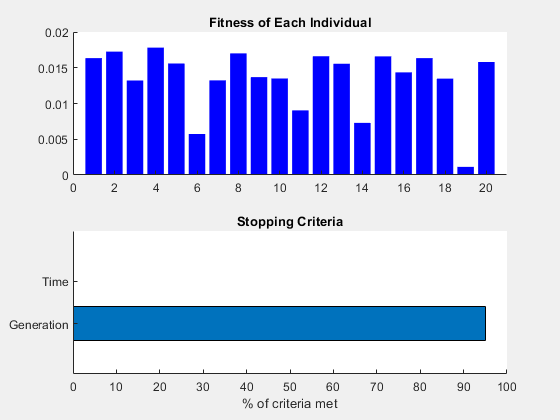

% Pass fixed parameters to objfun
objfun = @(x)objectiveFcn(x,a);

% Set nondefault solver options
options = optimoptions("gamultiobj","FunctionTolerance",0.001,...
    "PopulationSize",20,"MaxGenerations",20,"Display","iter","PlotFcn",...
    ["gaplotscores","gaplotstopping"]);

% Solve
[solution,objectiveValue] = gamultiobj(objfun,nVar,[],[],[],[],x0,x1,[],[],...
    options);


% Clear variables
clearvars objfun options


## Results

`Optimize` saves the solution to the workspace variable `solution`, and saves the objective function value at the solution to the workspace variable `objectiveValue`. 

View these variables.

% displaying results
solution

solution =     1.6623    0.2839    0.0361
    0.5377    0.5000    0.3750
    4.7902    0.3728    0.1358
    1.8419    0.3344    0.0870
    1.6623    0.2839    0.0361
   24.3185    0.3886    0.4863
    1.6935    0.2927    0.0664


objectiveValue

objectiveValue =     0.0163    0.0415         0
    0.0132    0.0003   39.2025
    0.0057    0.0195   26.5511
    0.0143    0.0662    7.1044
    0.0163    0.0415         0
    0.0011    0.0152   58.5705
    0.0158    0.0664    2.4236



kp = solution(1);
ki = solution(2);
kd = solution(3);

% setting PID values in Simulink Model
set_param('DC_Motor_Control_GA/PID_Controller', 'P', num2str(kp));
set_param('DC_Motor_Control_GA/PID_Controller', 'I', num2str(ki));
set_param('DC_Motor_Control_GA/PID_Controller', 'D', num2str(kd));

sim('DC_Motor_Control_GA');

toc % elasped time from the stopwatch

Elapsed time is 440.522466 seconds.


## Helper Functions — Local Functions

The following code creates the objective function. Modify this code for your problem.

function F = objectiveFcn(x,a)
disp(x)
% assigning solution to PID gains
kp = x(size(x,1),1);
ki = x(size(x,1),2);
kd = x(size(x,1),3);

% setting PID values in Simulink Model
set_param('DC_Motor_Control_GA/PID_Controller', 'P', num2str(kp));
set_param('DC_Motor_Control_GA/PID_Controller', 'I', num2str(ki));
set_param('DC_Motor_Control_GA/PID_Controller', 'D', num2str(kd));

% running Simulink Model
sim('DC_Motor_Control_GA');

t_res = stepinfo(y, tt);

% Fitness value - Integral of Absolute Error
ey = IAE(length(IAE));
est = abs(0.05 - t_res.SettlingTime);
eos = abs(0 - t_res.Overshoot);

F = [ey est eos];
end

*Copyright 2020 The MathWorks, Inc.*